# Solving for the Planar Orientation Distribution Function

Sections 5.2.1 and 5.3.1 discuss how to solve for the orientation distribution function $\psi_\phi ( \phi )$ when both the orientation and the deformation occur in a plane.  For the Folgar-Tucker model, the governing equation is Eqn. (5.28), 


$$   \frac{D \psi_\phi}{D t \;\;} 
    =  - \frac{\partial \;}{\partial \phi}  \left( \psi_\phi \dot{\phi}  \right)
   +  C_I \, \dot{\gamma} \frac{\partial^2 \psi_\phi}{\partial \phi^2} $$


Here $\dot{\phi}$ is the Jeffery expression for the rate of change of $\phi$, Eqn. (4.),


$$\dot{\phi} = -W_{12} - \xi D_{11} \sin (2\phi) + \xi D_{12} \cos(2\phi)$$


with $W_{12}$, $D_{11}$ and $D_{12}$ representing components of the vorticity and rate-of-deformation tensors, respectively.  

For a single material point we can treat $D \psi_\phi / Dt$ like the partial derivative, $\partial \psi_\phi / \partial t$.  The function `solvePsi2D` then uses a uniform finite difference grid in $\phi$ to solve the governing equation.  The finite difference equations are flux-conservative, and time stepping is fully implicit.  

Here is the calculation of $\psi_\phi (\phi, t)$for the Folgar-Tucker model in planar extensional flow, as shown in Fig. 5.3(a):

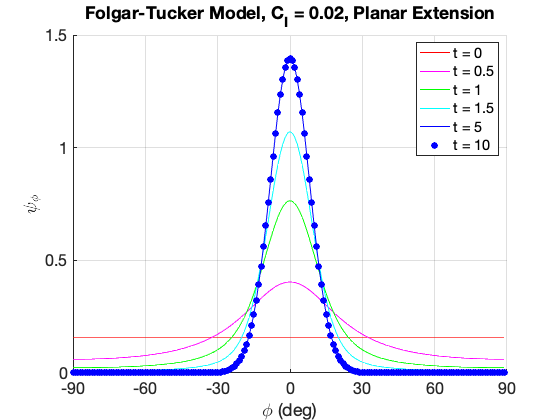

% Input Parameters:
CI     = 0.02;
xi     = 1;      % Particle shape factor
nnod   = 180;    % Number of nodes in phi = [-pi/2, pi/2)
L = zeros(2);    % Velocity gradient tensor (can be 2x2 or 3x3)
L(1,1) =  1;     % Planar elongation
L(2,2) = -1;

% Solution control:
dt     = 0.5;   % Time step for saving results
tmax   = 10;    % Ending time
Co     = 1;     % Max. Courant number; limits internal time steps
scheme = 'power';  % Finite differencing scheme ('central' or 'power')

% --- Solve for the planar orientation distribution function ---
[t, psi, phi] = solvePsi2D(L, CI, xi, tmax, dt, nnod, Co, scheme);

% Plot results at selected times
tplot  = [0, 0.5, 1, 1.5, 5, 10];  % Times to plot psi
lcolor = ['r', 'm', 'g', 'c', 'b', 'b']; % Colors for each time
figure; hold on
for i = 1:length(tplot)
    iplot = find(t == tplot(i), 1); % Index of this time in t
    if i < length(tplot) % Plot a smooth line for most time steps
        plot(rad2deg(phi), psi(:, iplot), 'k-', 'Color', lcolor(i))
    else % Plot points only for the last time step
        plot(rad2deg(phi), psi(:, iplot), 'ko', 'Color', lcolor(i), ...
            'MarkerEdgeColor', lcolor(i), 'MarkerFaceColor', lcolor(i))
    end
end
xlabel('\phi (deg)')
ylabel('$\psi_\phi$', 'Interpreter', 'Latex')
axis([-90, 90, 0, 1.5])
set(gca, 'FontSize', 16, 'Xtick', -90:30:90)
grid on
legend('t = 0', 't = 0.5', 't = 1', 't = 1.5', 't = 5', 't = 10')
title('Folgar-Tucker Model, C_I = 0.02, Planar Extension')

`solvePsi2D` returns results at time increments `dt`, but may take smaller sub-steps internally.  That stepping is controlled by the Courant number `Co`, and one should aways use Co $\le$ 1.  

This solution uses power-law upwind differencing, which stabilizes the solution when $\psi_\phi$ develops a strong peak.  Here is the final-time solution with central differencing, a smaller value of $C_I$ (which generates a sharper peak), and a coarser grid of points:

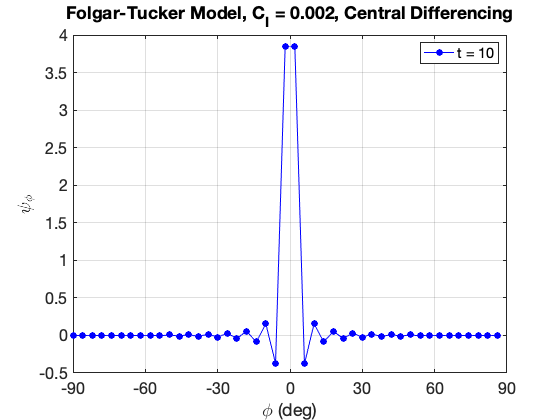

% Relying on other factors from above . . .
nnod = 45;
CI = 0.002;
scheme = 'central';    % Use central differencing
[t, psi, phi] = solvePsi2D(L, CI, xi, tmax, dt, nnod, Co, scheme);

% Plot the last time step
figure
plot(rad2deg(phi), psi(:,end), 'bo-', 'MarkerFaceColor', 'b')
xlabel('\phi (deg)')
ylabel('$\psi_\phi$', 'Interpreter', 'Latex')
legend('t = 10')
axval = axis;                       % Save the automatic axis limits
axis([-90, 90, axval(3), axval(4)]) % Only adjust the x-axis limits
set(gca, 'FontSize', 16, 'Xtick', -90:30:90)
grid on
title('Folgar-Tucker Model, C_I = 0.002, Central Differencing')

This solution has wiggles, and $\psi_\phi$ takes on some negative values, whcih are non-physical.  Try changing back to `scheme = 'power'`, or changing the value of `nnod`, then re-run this section to see the effect on the solution.